## Resistor-Inductor-Capacitor circuits

### 1. Series RLC

circuit = Circuit('circuits/rlc_series.txt');
circuit.list

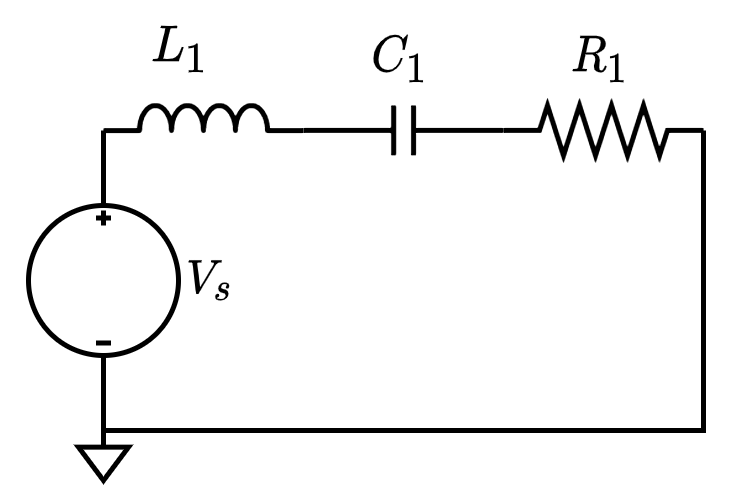

ELAB.analyze(circuit)

Say, you want expressions for node voltages.

circuit.symbolic_node_voltages
ELAB.ec2sd(circuit, 1, 3)

From the circuit, you can easily create a transfer function object, only giving the input and output nodes.

TF = ELAB.ec2tf(circuit, 1, 3)

Matlab can then be used to visualize the circuit behavior as with any other system. Plotting the Bode diagram, we see that this circuit acts as a band-pass-filter.

bode(TF); grid on;
step(TF); grid on;
impulse(TF); grid on;
t = 0:0.01:4;  % Arbitrary interval.
u = sin(10*t); % Arbitrary signal.
lsim(TF,u,t); grid on
nyquist(TF); grid on
nichols(TF); grid on
rlocus(TF); grid on

### 2. Parallel RLC

We can repeat the process to look at RLC in parallel.

circuit = Circuit('circuits/rlc_parallel.txt');
circuit.list

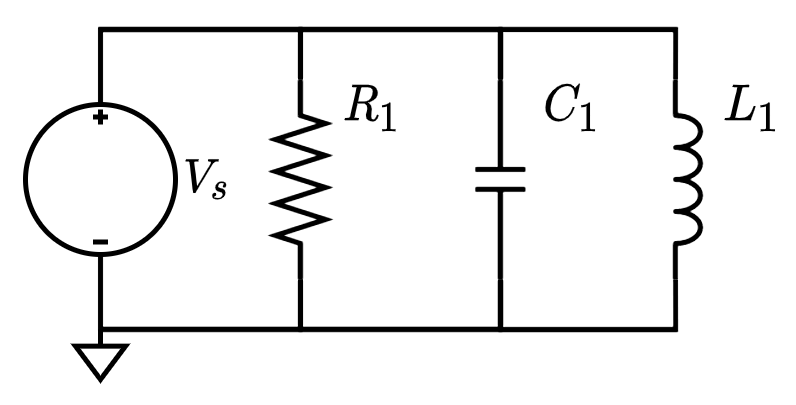

ELAB.analyze(circuit)
ELAB.evaluate(circuit)

In this case, because there is only one node besides ground, the transfer function is just the voltage at node 1.

You can of course input the equation directly into Matlab's transfer function. Plotting the Bode diagram show that this configuration acts as a frequency isolator.

TF = ELAB.sd2tf(rhs(circuit.numerical_node_voltages(1)))
bode(TF)

Feel free to try any combination of resistors, capacitors and inductors. 

### 3. Arbitrary RLC-circuits

circuit = Circuit('circuits/rlc_mix.txt');
circuit.list

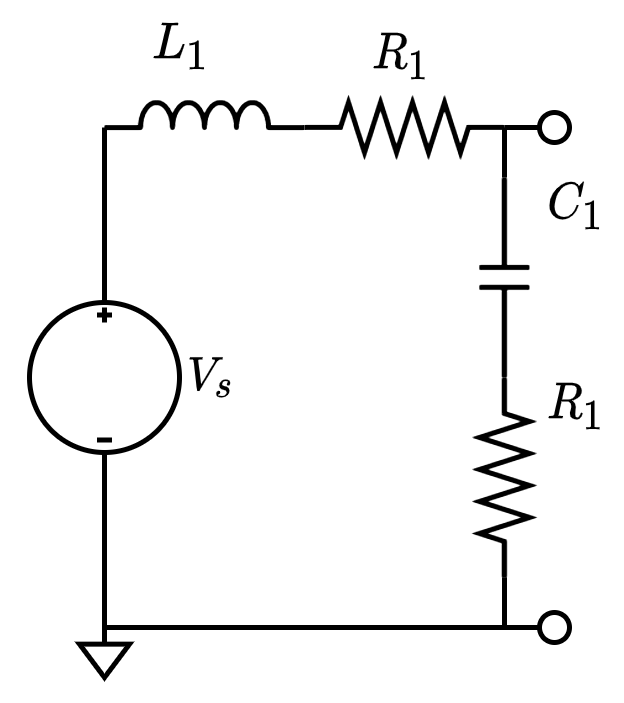

ELAB.analyze(circuit)
ELAB.ec2sd(circuit,1,3)
bode(ELAB.ec2tf(circuit,1,3))